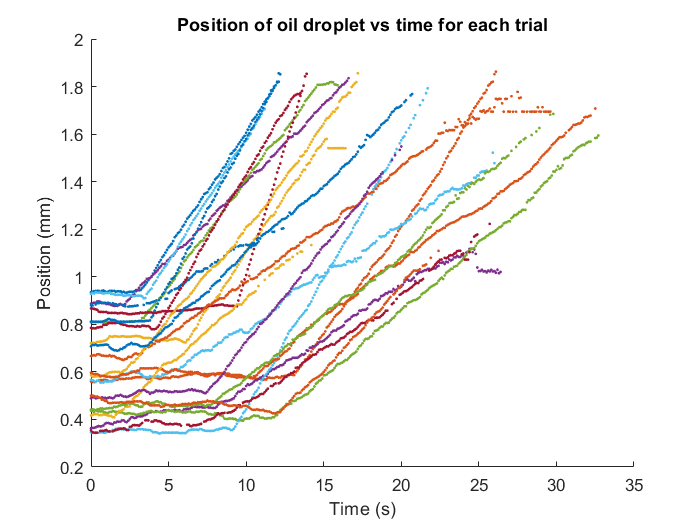

% MILLIKAN LAB

time = alltrialsprocesseddropped.(1);
num_trials = width(alltrialsprocesseddropped);
num_datapoints = height(alltrialsprocesseddropped);

for trial = 2:num_trials
    trial_data = [time';alltrialsprocesseddropped.(trial)'];
    
    % cleaning out the zeros
    for i = 1:num_datapoints
        if trial_data(2,i) == 0
            trial_data(2,i) = NaN;
        end
    end
    
    % plotting data on graph
    scatter(trial_data(1,:), trial_data(2,:), 3, 'filled')
    hold on
end

xlabel('Time (s)')
ylabel('Position (mm)')
title('Position of oil droplet vs time for each trial')

hold off




% Graphing linear fit example:

ydata = V.(3)';
xdata = V.(2)';
yFunc = @(x, xdata) x(1).*xdata + x(2);

% fitting shit
x0 = [20, 20];
mb = lsqcurvefit(yFunc, x0, xdata, ydata)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


mb =     0.0441    0.3842


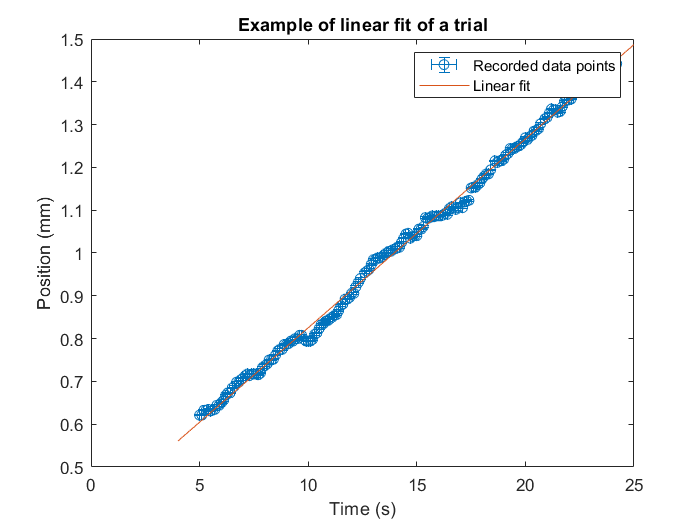


% fitted function
x = [4 25];
y_fit = yFunc(mb, x);

%error
y_err = ones(1, 190) .* 0.00185;
x_err = ones(1, 190) .* 0;

errorbar(xdata, ydata, y_err, y_err, x_err, x_err, 'o');
hold on
plot(x, y_fit)
%scatter(xdata, ydata)
xlabel('Time (s)')
ylabel('Position (mm)')
title('Example of linear fit of a trial')
legend('Recorded data points', 'Linear fit')